## How to plot figures (in matlab)

2021-1-12 -  Maureen Hagan <maureen.hagan@monash.edu>

This script serves two functions - offer some general principles on plotting data (regardless of how you make your plots - matlab/graph pad/R/etc) and give some practical examples of how to make publication quality figures in matlab that implement these principles.

### Principles for plotting figures

These things may seem intuitive, but they're the most common mistakes I see when watching student presentations or reading a thesis. Figures are the way we communicate our data to an audience. Just like clear and concise writing, it is imperiative that your figures are legible and easy to understand. Your reader/viewer does not have as much insight into your data as you do, and they need to be able to digest your findings quickly and easily. No one is going to spend hours pouring over each figure in your thesis/grant/presnentation/manuscript. If they can't figure it out quickly, they'll most likely get frustrated and disregard it. As much as the text you write, the figures are telling the story of your results.

- **Always label your axes. **This seems obvious, but it is amazing how often it's missed. Every axis needs to be properly labeled - with units.

- **Choose legible fonts. **There is no point in labeling your axes if the text is so small no one can read it. Choose sans serif fonts (unless required to use Times New Roman). Minimum san serif font sizes should be 10 for figures in text (manuscripts/grants) and 28 for presentations (posters/talks). If you're required to use Times New Roman - up it to 12 and 30 repsectively. And that's the *minimum*, important headings/text should be larger (particularly in presentations).

- **Color should be used to convey specific information.** Using color can be very helpful - but only if it conveys specific information about the data. Avoid using color gratuitously. Unnecessary color is distracting and confusing to the reader. Colors should convey specific information about the data and be used consistently throughout the document/presnetatation. For example, if you use 'red' to indicate 'direction selective cells' and 'blue' to indicate 'non-direction selective cells' this shoudl be consistent in every figure. And, critically, red and blue should not be used for anything else in the document/presentation. Also, because color is conveying information the colors should be *accessible* to all readers, regardless of visual ability. More on this below, with resources for color-blind friendly color schemes.

## Implementing these principles in matlab

Matlab is often critized for its plotting functions, and, to be fair, the default settings for figures and colors are pretty horrible. But you can quite easily reset all of the defaut settings to something more acceptable and visually appealing.

For these examples, I've provided a mat file that has some data from my Cerebral Cortex paper. The mat file is in the same directory as this script, so cd to where ever your put this on your machine.

load Examples.mat % Example data for plotting

Now let's plot some example figures:

#### Scatter plot

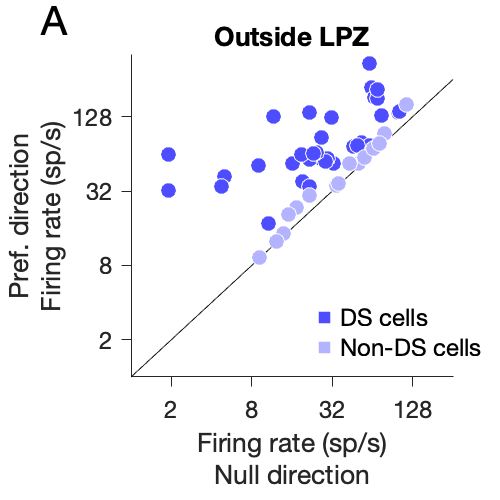

% first let's set some variables to make our plot looks pretty

% axis limits:
xmin = Examples.Scatter.axis(1); xmax = Examples.Scatter.axis(2);
ymin = Examples.Scatter.axis(3); ymax = Examples.Scatter.axis(4);
xlen = xmax - xmin; ylen = ymax - ymin;
% these are super handy variables to set if you want to plot things like
% text on your figure, for legends, panel labels, etc (see below)

% this plot contains both direction selective and non-direction selective
% cells from outside the lesion projection zone in MT - so I want a different color for each:
% blue is my color for outside the LPZ, and I have two different shadings
% for direction selective (ds) and non-direction selective (nds)

% color can be any RGB triplet! 
ou_ds_color = [0.3 0.3 1]; % dark blue
ou_nds_color = [0.7 0.7 1]; % light blue

% now lets plot our figure:

figure('Units','points','Position',[0 0 250 250]); % you can set the size of your figure, here i've used points but you can change to inches/cm or put in paper size. handy if this is going to be a subpanel of a bigger figure put together elsewhere (powerpoint/illustrator/etc)
hold on;

% plot unity line
line([xmin xmax], [ymin ymax],'Color',[0, 0, 0],'LineWidth',0.5);

% firing rates
plot(log(Examples.Scatter.ou_null_ds),log(Examples.Scatter.ou_pref_ds),'o','Color',[1 1 1],'MarkerFaceColor',ou_ds_color, 'MarkerSize',8)
plot(log(Examples.Scatter.ou_null_nds),log(Examples.Scatter.ou_pref_nds),'o','Color',[1 1 1],'MarkerFaceColor',ou_nds_color, 'MarkerSize',8)

set(gca,'XTick', log([2 8 32 128]));
set(gca,'XTickLabel', {'2' '8' '32' '128'});
set(gca,'YTick', log([2 8 32 128]));
set(gca,'YTickLabel', {'2' '8' '32' '128'});
set(gca,'FontName', 'Helvetica', 'FontAngle','normal','FontSize',12);
set(gca,'TickDir', 'out');
set(gca,'TickLength', [0.03,0.035]);

% always label your axes!!!
ylabel({'Pref. direction' 'Firing rate (sp/s)'})
xlabel({'Firing rate (sp/s)' 'Null direction'})
title('Outside LPZ') % you dont necessarily need a title, but sometimes it helps.

%legend - there is a built in legend in matlab but it sucks so i make my
%own:
plot(.6*xmax, .2*ymax,'s','Color',[1 1 1],'MarkerFaceColor',ou_ds_color, 'MarkerSize',8)
text(.65*xmax, .2*ymax,'DS cells','FontName','Helvetica', 'FontAngle','normal','FontSize',12,'HorizontalAlignment','left');
plot(.6*xmax, .1*ymax,'s','Color',[1 1 1],'MarkerFaceColor',ou_nds_color, 'MarkerSize',8)
text(.65*xmax, .1*ymax,'Non-DS cells','FontName','Helvetica', 'FontAngle','normal','FontSize',12,'HorizontalAlignment','left');

% plot panel ID - useful if you have multiple panels
text(xmin-0.2*xlen,ymax+0.2*ylen,'A','FontName', 'Helvetica', 'FontAngle','normal','FontSize',20,'HorizontalAlignment','right');

axis([xmin xmax ymin ymax])
axis equal % if the units on each axis are the same (here, they're both firing rates), this ensures that 1 sp/s is the same on both the x and y axis.
axis square % not necessary, but a handy command to know anyway for making things pretty. this will make a square plot.

Some notes about this figure:

- Font - I find 'Helvetica' exports nicely to other software (ie Illustrator) but others may work well too.

- Choose line widths/marker sizes that are appropriate for the size of the figure so the data is clearly visible.

- Tick marks - Outward tick marks ensure ticks dont get covered by data. Specifying tick length allows you to set them to a visible size.

- This figures uses 'log' axes instead of 'linear' - this can be appropriate for  data that don't follow normal distributions (ie firing rates, reaction times)  or data that is presented as ratios (ie contrast).

#### Examples vs Populations

Often a good practice is plotting example data (of a single cell/trial etc) and then plotting the population. When possible, its nice to show where your example sits in the distrubtion of the population. It gives the reader a better sense of how 'typical' your beautiful example is of your results.

#### Histograms

stacked vs overlapping

### Resources for using color 

#### Accessibility

Whenever possible, choose colors that are accessible to people of all visual abilities. This is not as simple as avoiding the well known 'bad' combinations like red-green and blue-green. Here are some good resources for choosing colorblind safe colors:

- [https://colorbrewer2.org/](https://colorbrewer2.org/) - helps craft color schemes/palletes. Make sure you select 'Colorblind safe'

- [https://colororacle.org/](https://colororacle.org/) - free color blindness simulator - will temporarily render your computer screen as it would be seen by people of different visual abilities. great for checking your figures.

#### Color maps

The matlab color maps are all awful. Choose a color scale that is perceptually uniform - meaning the increments between colors are are uniform in contrast to more accurately represent your data. In general, these maps are also more colorblind-friendly, but you can find maps that are specifically designed to be accessible as well. Circular maps (for plotting angular data) are particularly difficult for colorblindness - I have not found a great one. But choosing a perceptually uniform one is far superior to one that is not. Here are some places to look:

- [https://colorcet.com/](https://colorcet.com/)

- [https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps](https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps) 

### For more inspiration...

Looking for more examples of great figures? Here is a non-exhaustive list of some labs that consistently make great plots:

- Tony Movshon: [https://scholar.google.com.au/citations?hl=en&user=4Ma6NAYAAAAJ&view_op=list_works&sortby=pubdate](https://scholar.google.com.au/citations?hl=en&user=4Ma6NAYAAAAJ&view_op=list_works&sortby=pubdate)

- Eero Simoncelli: [https://scholar.google.com.au/citations?hl=en&user=MplR7_cAAAAJ&view_op=list_works&sortby=pubdate](https://scholar.google.com.au/citations?hl=en&user=MplR7_cAAAAJ&view_op=list_works&sortby=pubdate)

- Also read Edward Tufte - [https://www.edwardtufte.com/](https://www.edwardtufte.com/) He has written a lot about data visualization.